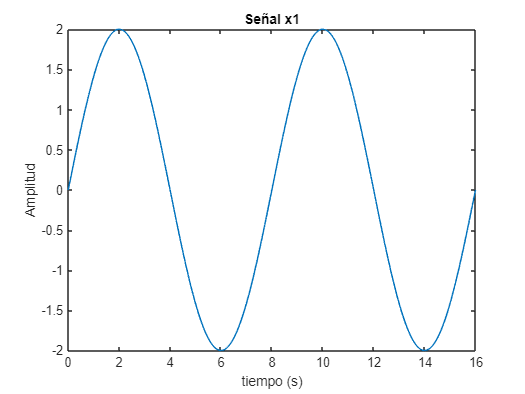

%Parametros
clc; clear all; close all

A = 2;                   % Amplitud señal
Fs = 8000;               % Frecuencia muestreo
Ts = 1/Fs;               % Periodo de muestreo
tiempo_final = 16;       % Duración de la señal % T = 8, 2*T
t = (0:Ts:tiempo_final-Ts)';  % Eje tiempo
Fsignal = 1/8;           % Frecuencia señal
x1 = A*sin(2*pi*Fsignal*t);    % Señal
L = length(x1);          % Tamaño Señal

figure(1);
plot(t,x1);
xlabel('tiempo (s)');
ylabel('Amplitud')
title('Señal x1');

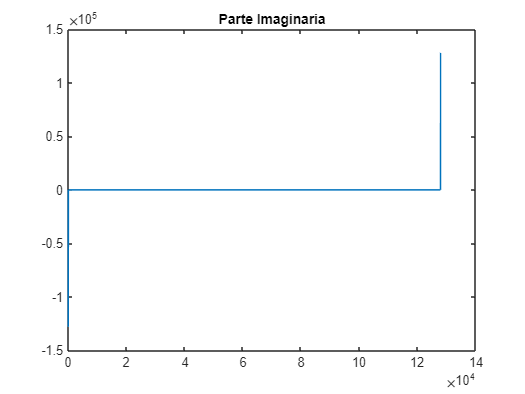

% Espectro de frecuencias
X1 = fft(x1);

parteImaginaria = imag(X1);
parteReal = real(X1);


figure()
plot(parteImaginaria)
title('Parte Imaginaria')

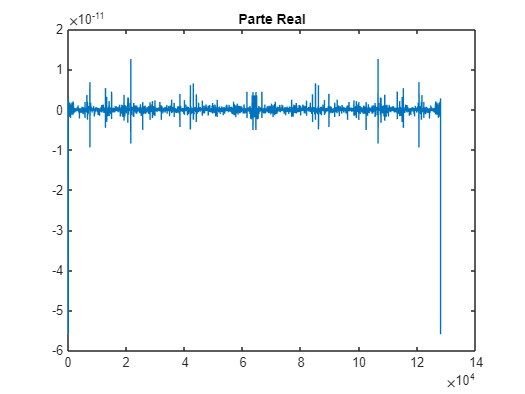


figure()
plot(parteReal)
title('Parte Real')

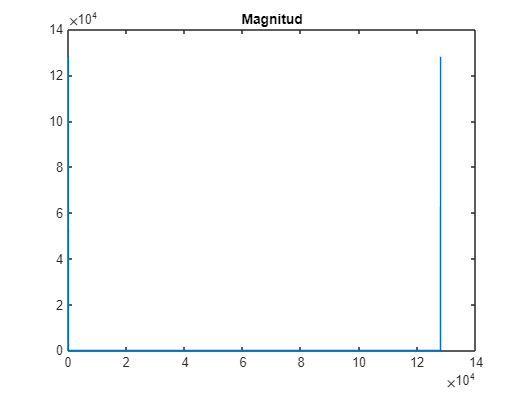


figure()
plot(abs(X1))
title('Magnitud')

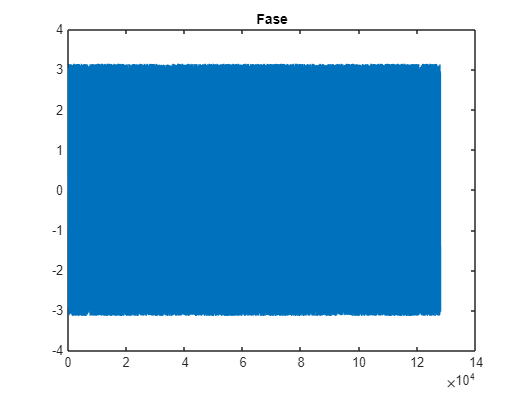



figure()
plot(angle(X1))
title('Fase')

**VENTANA TRIANGULAR - BARLETT**

%VENTANA TRIANGULAR - BARLETT

ventanaBarlett = bartlett(50)

ventanaBarlett =          0
    0.0408
    0.0816
    0.1224
    0.1633
    0.2041
    0.2449
    0.2857
    0.3265
    0.3673


ventanaBarlett = ventanaBarlett';
ventanaBarlett = [ventanaBarlett zeros(1, 105)]

ventanaBarlett =          0    0.0408    0.0816    0.1224    0.1633    0.2041    0.2449    0.2857    0.3265    0.3673    0.4082    0.4490    0.4898    0.5306    0.5714    0.6122    0.6531    0.6939    0.7347    0.7755    0.8163    0.8571    0.8980    0.9388    0.9796    0.9796    0.9388    0.8980    0.8571    0.8163    0.7755    0.7347    0.6939    0.6531    0.6122    0.5714    0.5306    0.4898    0.4490    0.4082    0.3673    0.3265    0.2857    0.2449    0.2041    0.1633    0.1224    0.0816    0.0408         0


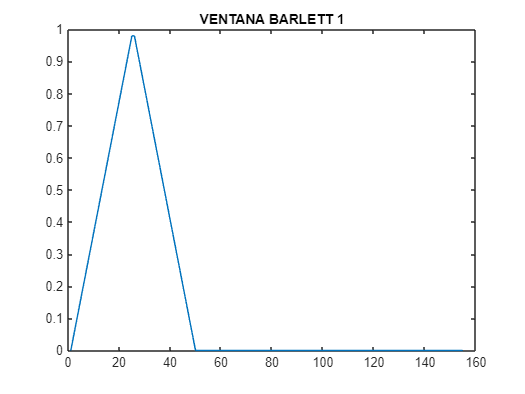

plot(ventanaBarlett)
title('VENTANA BARLETT 1')

truncadoBarlett = ventanaBarlett.*x_muestreado

Unrecognized function or variable 'x_muestreado'.

stem(truncadoBarlett)
title('TRUNCADO BARLETT 1')

[h, w] = freqz(truncadoBarlett);
plot(w/pi, abs(h))
grid()
title("Respuesta en Frecuencia Truncada Barlett 2")
xlabel("Frecuencia")
ylabel("Amplitud")

**VENTANA HAMMING**

%VENTANA HAMMING 1
ventanaHamming = hamming(100);
ventanaHamming = ventanaHamming';
ventanaHamming = [ventanaHamming zeros(1, 55)]
plot(ventanaHamming)
title('VENTANA HAMMING 1')
truncadoHamming = ventanaHamming.*x_muestreado
plot(truncadoHamming)
title('TRUNCADO HAMMING 1')

%VENTANA HAMMING 2
M = 100
i = 0:1:M-1
ventanaHamming2 = 0.54 -0.46*cos(2*pi*i/(M-1));
stem(ventanaHamming2)
title('VENTANA HAMMING 2 (100 puntos)')

%RESIZING
ventanaHamming2 = [ventanaHamming2 zeros(1,55)];
truncadoHamming2 = ventanaHamming2.*x_muestreado;
stem(truncadoHamming2)
title('TRUNCADO HAMMING 2')

[h, w] = freqz(truncadoHamming2);
plot(w/pi, abs(h))
grid()
title("Respuesta en Frecuencia Truncada Hamming 2")
xlabel("Frecuencia")
ylabel("Amplitud")

**VENTANA HANNING**

%VENTANA HANNING 1
ventanaHanning = hanning(150);
ventanaHanning = ventanaHanning';
ventanaHanning = [ventanaHanning zeros(1, 5)];
x_muestreado
stem(ventanaHanning)
title('VENTANA HANNING 1')
truncadoHanning = ventanaHanning.*x_muestreado
stem(truncadoHanning)
title('TRUNCADO HANNING 1')

%VENTANA HANNING 2
M = 150
i = 0:1:M-1
ventanaHanning2 = 0.5 -0.5*cos(2*pi*i/(M-1));
stem(ventanaHanning2)
title('VENTANA HANNING 2')

%RESIZING
ventanaHanning2 = [ventanaHanning2 zeros(1,5)];
truncadoHanning2 = ventanaHanning2.*x_muestreado;
stem(truncadoHanning2)
title('TRUNCADO HANNING 2')

[h, w] = freqz(truncadoHanning2);
plot(w/pi, abs(h))
grid()
title("Respuesta en Frecuencia Truncada Hanning 2")
xlabel("Frecuencia")
ylabel("Amplitud")
